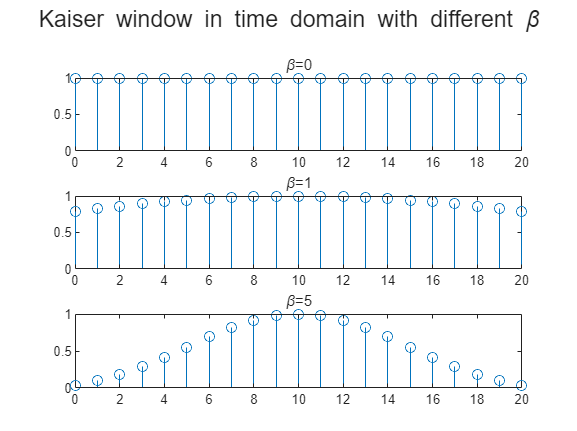

clc;clear;close all;
load nspeech2.mat;

N=0:20;
k1=kaiser(21,0);
k2=kaiser(21,1);
k3=kaiser(21,5);
[X1,w1]=DTFT(k1,512);
[X2,w2]=DTFT(k2,512);
[X3,w3]=DTFT(k3,512);

figure;
sgtitle('Kaiser window in time domain with different \beta')
subplot(311);stem(N,k1);title('\beta=0');
subplot(312);stem(N,k2);title('\beta=1');
subplot(313);stem(N,k3);title('\beta=5');

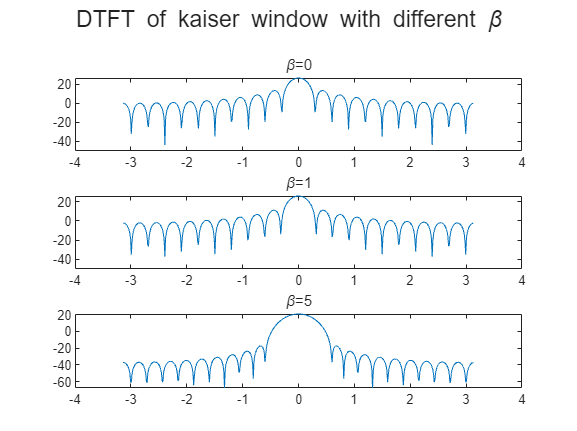

figure;
sgtitle('DTFT of kaiser window with different \beta')
subplot(311);plot(w1,20*log10(abs(X1)));title('\beta=0');
subplot(312);plot(w2,20*log10(abs(X2)));title('\beta=1');
subplot(313);plot(w3,20*log10(abs(X3)));title('\beta=5');

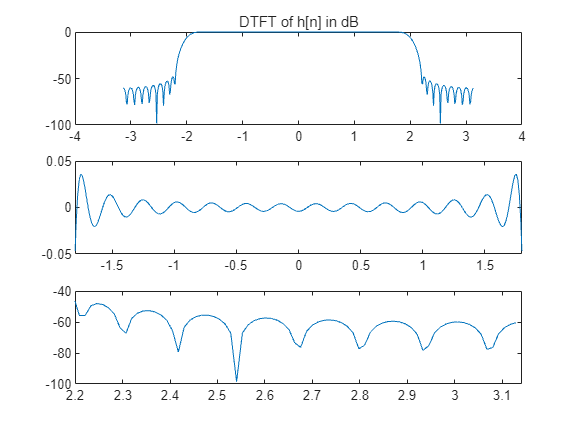

kx=kaiser(43,4.0909);
h=LPFTrunc(43).*kx';
[X4,w4]=DTFT(h,512);
% figure;
% stem(kx);
mag_X4=20*log10(abs(X4));
figure
subplot(311);
plot(w4,mag_X4);title('DTFT of h[n] in dB')
subplot(312)
plot(w4,mag_X4),xlim([-1.8,1.8])
subplot(313)
plot(w4,mag_X4),xlim([2.2,pi])

res2=conv(h,nspeech2);
ripple1= max(abs(X4(abs(w4)<=1.8)))-1

ripple1 = 0.0041

ripple2= max(abs(X4(abs(w4)>=2.2)))

ripple2 = 0.0039

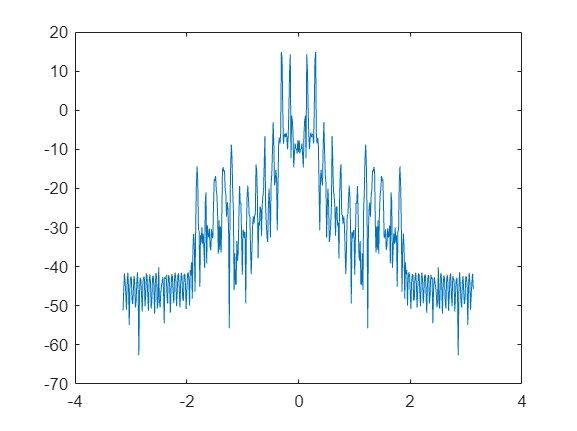

% sound(res2);
[X5,w5]=DTFT(res2(20000:20400),512);
figure;
plot(w5,20*log10(abs(X5)));

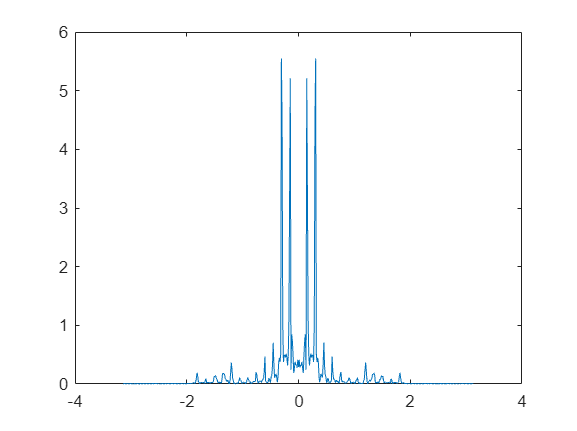

figure
plot(w5,abs(X5));